clear;
close all;
clc;

linewidth  = 2;
fontname   = 'Times New Roman';
fontsize   = 20;
markersize = 10;

colors = [0.0000 0.0000 0.0000;
          0.0000 0.4470 0.7410;
          0.8500 0.3250 0.0980;
          0.9290 0.6940 0.1250;
          0.4940 0.1840 0.5560;
          0.4660 0.6740 0.1880;
          0.3010 0.7450 0.9330;
          0.6350 0.0780 0.1840];

## **NETWORK PARAMETERS**

N_BLK = 10000;

M = 100;
K = 4;
H = (randn(M, K) + 1i * randn(M, K)) / sqrt(2);

B = 4;
M_QAM = 2^B;

SNR = -10:50;
N_SNR = length(SNR);
snr = 10.^(SNR/10);

## MEMORY ALLOCATION

s = zeros(N_BLK, K);

BER_ZF = zeros(1, N_SNR);
BER_MF = zeros(1, N_SNR);
BER_MMSE = zeros(1, N_SNR);

bit_array = randi([0,1], B*N_BLK, K);

for users_idx = 1:K
    s(:, users_idx) = qammod(bit_array(:,users_idx), M_QAM, 'InputType', 'bit'); 
end
     
Ps = vecnorm(s).^2/N_BLK;

precoder_ZF = conj(H) / (H.' * conj(H));
precoder_MF = conj(H) ./ (vecnorm(H).^2);

precoder_MMSE = zeros(M, K, N_SNR);
for snr_idx = 1:N_SNR
    precoder_MMSE(:,:,snr_idx)  = conj(H) / (H.' * conj(H) + diag(1/snr(snr_idx)));
end

x_ZF = precoder_ZF * s.';
x_MF = precoder_MF * s.';
x_MMSE = zeros(M, N_BLK, N_SNR);

for snr_idx = 1:N_SNR
    x_MMSE(:,:,snr_idx) = precoder_MMSE(:,:,snr_idx) * s.';
end

x_ZF_normalized = zeros(size(x_ZF)); 
x_MF_normalized = zeros(size(x_MF));
x_MMSE_normalized = zeros(size(x_MMSE));

for m = 1:M
    Px_ZF = norm(x_ZF(m, :))^2/length(x_ZF(:,m));
    Px_MF = norm(x_MF(m, :))^2/length(x_MF(:,m));
    Px_MMSE = norm(x_MMSE(m, :))^2/length(x_MMSE(:,m));
    
    x_ZF_normalized(m, :) = x_ZF(m, :) / sqrt(Px_ZF);
    x_MF_normalized(m, :) = x_MF(m, :) / sqrt(Px_MF);
    x_MMSE_normalized(m, :) = x_MMSE(m, :) / sqrt(Px_MMSE);
end

v = sqrt(0.5) * (randn(K, N_BLK) + 1i*randn(K, N_BLK));

Pv = vecnorm(v,2,2).^2/N_BLK;

v_normalized = v./sqrt(Pv);

for snr_idx = 1:N_SNR        
    y_ZF = H.' * sqrt(snr(snr_idx)) * x_ZF_normalized + v_normalized; 
    y_MF = H.' * sqrt(snr(snr_idx)) * x_MF_normalized + v_normalized;
    y_MMSE = H.' * (sqrt(snr(snr_idx)) * x_MMSE_normalized(:,:,snr_idx)) + v_normalized; 

    % Demodulação e cálculo da BER para ZF
    bit_received_ZF = zeros(B*N_BLK, K);
    for users_idx = 1:K
        s_received_ZF = y_ZF(users_idx, :).';
        Ps_received_ZF = norm(s_received_ZF)^2/N_BLK;
        bit_received_ZF(:, users_idx) = qamdemod(sqrt(Ps(users_idx)/Ps_received_ZF) * s_received_ZF, M_QAM, 'OutputType', 'bit');
    end

    [~, BER_ZF(snr_idx)] = biterr(bit_received_ZF, bit_array);

    % Demodulação e cálculo da BER para MF
    bit_received_MF = zeros(B*N_BLK, K); % Reset for MF
    for users_idx = 1:K
        s_received_MF = y_MF(users_idx, :).';
        Ps_received_MF = norm(s_received_MF)^2/N_BLK;
        bit_received_MF(:, users_idx) = qamdemod(sqrt(Ps(users_idx)/Ps_received_MF) * s_received_MF, M_QAM, 'OutputType', 'bit');
    end

    [~, BER_MF(snr_idx)] = biterr(bit_received_MF, bit_array);

    % Demodulação e cálculo da BER para MMSE
    bit_received_MMSE = zeros(B*N_BLK, K);
    for users_idx = 1:K
        s_received_MMSE = y_MMSE(users_idx, :).';
        Ps_received_MMSE = norm(s_received_MMSE)^2/N_BLK;
        bit_received_MMSE(:, users_idx) = qamdemod(sqrt(Ps(users_idx)/Ps_received_MMSE) * s_received_MMSE, M_QAM, 'OutputType', 'bit');
    end

    [~, BER_MMSE(snr_idx)] = biterr(bit_received_MMSE, bit_array);
end

## BER vs SNR

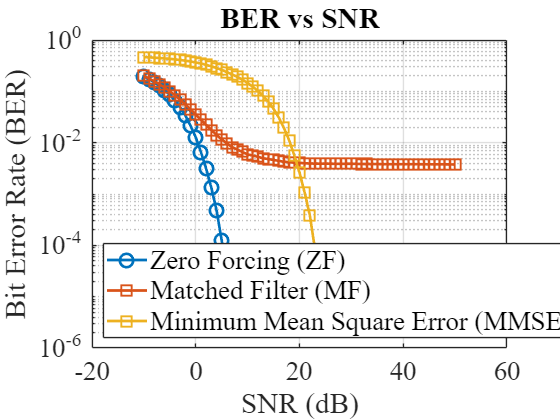

figure;
semilogy(SNR, BER_ZF, 'o-', 'LineWidth', linewidth, 'MarkerSize', markersize, 'Color', colors(2,:)); hold on;
semilogy(SNR, BER_MF, 's-', 'LineWidth', linewidth, 'MarkerSize', markersize, 'Color', colors(3,:));
semilogy(SNR, BER_MMSE, 's-', 'LineWidth', linewidth, 'MarkerSize', markersize, 'Color', colors(4,:));
grid on;
xlabel('SNR (dB)', 'FontName', fontname, 'FontSize', fontsize);
ylabel('Bit Error Rate (BER)', 'FontName', fontname, 'FontSize', fontsize);
legend('Zero Forcing (ZF)', 'Matched Filter (MF)', 'Minimum Mean Square Error (MMSE)', 'Location', 'southwest', 'FontSize', fontsize);
title('BER vs SNR', 'FontName', fontname, 'FontSize', fontsize);
set(gca, 'FontName', fontname, 'FontSize', fontsize);
hold off;

## Real x Imag (ZF)

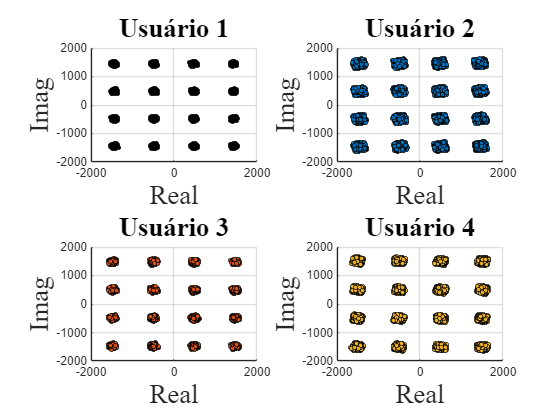

% Sinal decodificado
figure;
for users_idx = 1:K
    subplot(2, 2, users_idx);
    
    s_received_ZF = y_ZF(users_idx, :).';

    scatter(real(s_received_ZF), imag(s_received_ZF), markersize, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', colors(users_idx, :));
    xlabel('Real', 'FontName', fontname, 'FontSize', fontsize);
    ylabel('Imag', 'FontName', fontname, 'FontSize', fontsize);
    title(['Usuário ', num2str(users_idx)], 'FontName', fontname, 'FontSize', fontsize);
    grid on;
end

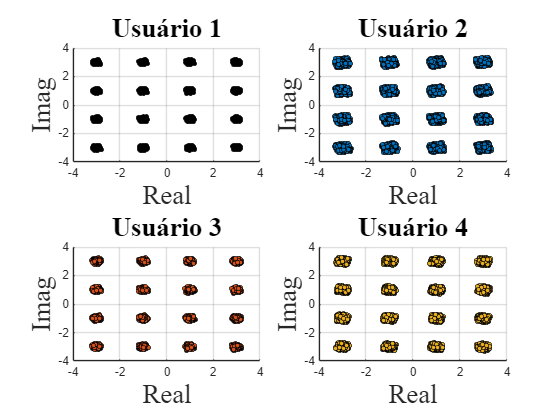

% Sinal decodificado (com normalização)
figure;
for users_idx = 1:K
    subplot(2, 2, users_idx);
    
    s_received_ZF = y_ZF(users_idx, :).';
    
    Ps_received_ZF = norm(s_received_ZF)^2 / N_BLK;
    s_received_ZF_normalized = sqrt(Ps(users_idx) / Ps_received_ZF) * s_received_ZF;
    
    scatter(real(s_received_ZF_normalized), imag(s_received_ZF_normalized), markersize, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', colors(users_idx, :));
    xlabel('Real', 'FontName', fontname, 'FontSize', fontsize);
    ylabel('Imag', 'FontName', fontname, 'FontSize', fontsize);
    title(['Usuário ', num2str(users_idx)], 'FontName', fontname, 'FontSize', fontsize);
    grid on;
end

## Real x Img (MF)

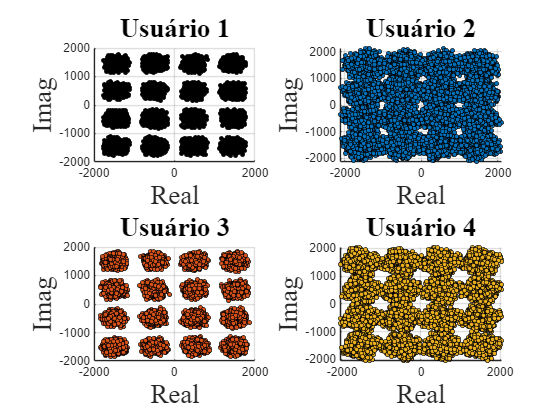

% Sinal decodificado
figure;
for users_idx = 1:K
    subplot(2, 2, users_idx);
    
    s_received_MF = y_MF(users_idx, :).';

    scatter(real(s_received_MF), imag(s_received_MF), markersize, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', colors(users_idx, :));
    xlabel('Real', 'FontName', fontname, 'FontSize', fontsize);
    ylabel('Imag', 'FontName', fontname, 'FontSize', fontsize);
    title(['Usuário ', num2str(users_idx)], 'FontName', fontname, 'FontSize', fontsize);
    grid on;
end

% Sinal decodificado (com normalização)
figure;
for users_idx = 1:K
    subplot(2, 2, users_idx);
    
    s_received_ZF = y_ZF(users_idx, :).';
    
    Ps_received_ZF = norm(s_received_ZF)^2 / N_BLK;
    s_received_ZF_normalized = sqrt(Ps(users_idx) / Ps_received_ZF) * s_received_ZF;
    
    scatter(real(s_received_ZF_normalized), imag(s_received_ZF_normalized), markersize, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', colors(users_idx, :));
    xlabel('Real', 'FontName', fontname, 'FontSize', fontsize);
    ylabel('Imag', 'FontName', fontname, 'FontSize', fontsize);
    title(['Usuário ', num2str(users_idx)], 'FontName', fontname, 'FontSize', fontsize);
    grid on;
end

## Real x Imag (MMSE)

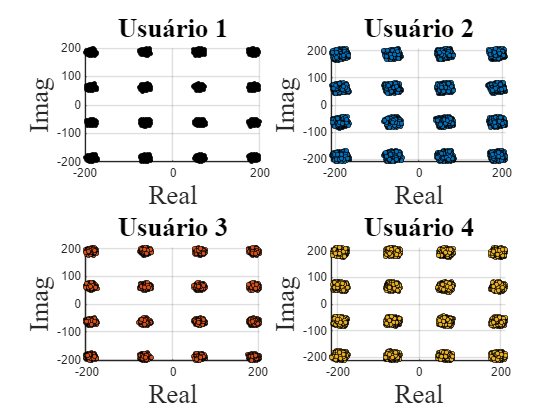

% Sinal decodificado
figure;
for users_idx = 1:K
    subplot(2, 2, users_idx);
    
    s_received_MMSE = y_MMSE(users_idx, :).';

    scatter(real(s_received_MMSE), imag(s_received_MMSE), markersize, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', colors(users_idx, :));
    xlabel('Real', 'FontName', fontname, 'FontSize', fontsize);
    ylabel('Imag', 'FontName', fontname, 'FontSize', fontsize);
    title(['Usuário ', num2str(users_idx)], 'FontName', fontname, 'FontSize', fontsize);
    grid on;
end

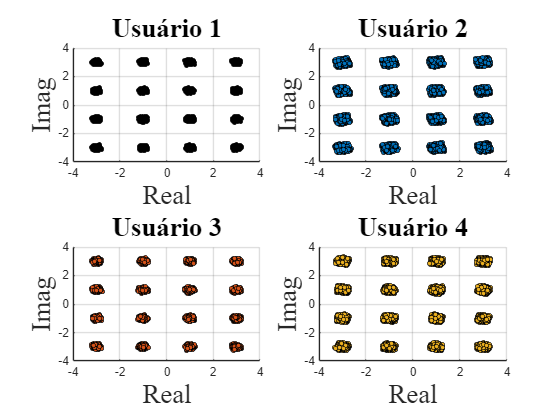

% Sinal decodificado (com normalização)
figure;
for users_idx = 1:K
    subplot(2, 2, users_idx);
    
    s_received_MMSE = y_MMSE(users_idx, :).';
    
    Ps_received_MMSE = norm(s_received_MMSE)^2 / N_BLK;
    s_received_MMSE_normalized = sqrt(Ps(users_idx) / Ps_received_MMSE) * s_received_MMSE;
    
    scatter(real(s_received_MMSE_normalized), imag(s_received_MMSE_normalized), markersize, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', colors(users_idx, :));
    xlabel('Real', 'FontName', fontname, 'FontSize', fontsize);
    ylabel('Imag', 'FontName', fontname, 'FontSize', fontsize);
    title(['Usuário ', num2str(users_idx)], 'FontName', fontname, 'FontSize', fontsize);
    grid on;
end

## BER p/ user

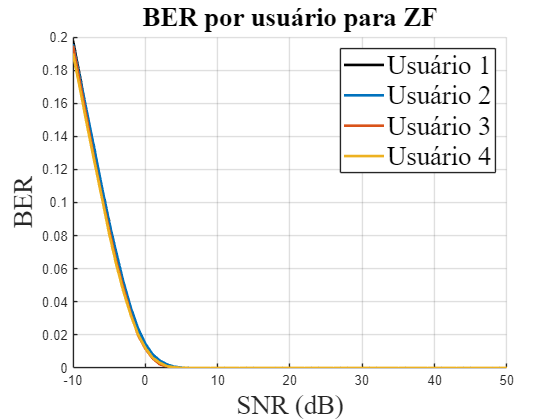

% Inicialize os arrays de BER para cada usuário
BER_ZF_individual = zeros(K, N_SNR);  % Para cada usuário e SNR
BER_MF_individual = zeros(K, N_SNR);  % Para cada usuário e SNR

for snr_idx = 1:N_SNR        
    y_ZF = H.' * sqrt(snr(snr_idx)) * x_ZF_normalized + v_normalized; 
    y_MF = H.' * sqrt(snr(snr_idx)) * x_MF_normalized + v_normalized;

    % Demodulação e cálculo da BER para ZF
    bit_received_ZF = zeros(B*N_BLK, K);
    for users_idx = 1:K
        s_received_ZF = y_ZF(users_idx, :).';
        
        Ps_received_ZF = norm(s_received_ZF)^2/N_BLK;

        % Demodulação para ZF
        bit_received_ZF(:, users_idx) = qamdemod(sqrt(Ps(users_idx)/Ps_received_ZF) * s_received_ZF, M_QAM, 'OutputType', 'bit');
    end
    
    % Calcule a BER individual de cada usuário usando ZF
    for users_idx = 1:K
        [~, BER_ZF_individual(users_idx, snr_idx)] = biterr(bit_received_ZF(:, users_idx), bit_array(:, users_idx));
    end

    % Demodulação e cálculo da BER para MF
    bit_received_MF = zeros(B*N_BLK, K); % Reset para MF
    for users_idx = 1:K
        s_received_MF = y_MF(users_idx, :).';

        Ps_received_MF = norm(s_received_MF)^2/N_BLK;

        % Demodulação para MF
        bit_received_MF(:, users_idx) = qamdemod(sqrt(Ps(users_idx)/Ps_received_MF) * s_received_MF, M_QAM, 'OutputType', 'bit');
    end
    
    % Calcule a BER individual de cada usuário usando MF
    for users_idx = 1:K
        [~, BER_MF_individual(users_idx, snr_idx)] = biterr(bit_received_MF(:, users_idx), bit_array(:, users_idx));
    end
end

figure;
hold on;
for users_idx = 1:K
    semilogy(SNR, BER_ZF_individual(users_idx, :), 'LineWidth', linewidth, 'Color', colors(users_idx, :));
end
hold off;
xlabel('SNR (dB)', 'FontName', fontname, 'FontSize', fontsize);
ylabel('BER', 'FontName', fontname, 'FontSize', fontsize);
title('BER por usuário para ZF', 'FontName', fontname, 'FontSize', fontsize);
legend(arrayfun(@(x) sprintf('Usuário %d', x), 1:K, 'UniformOutput', false), 'FontName', fontname, 'FontSize', fontsize);
grid on;

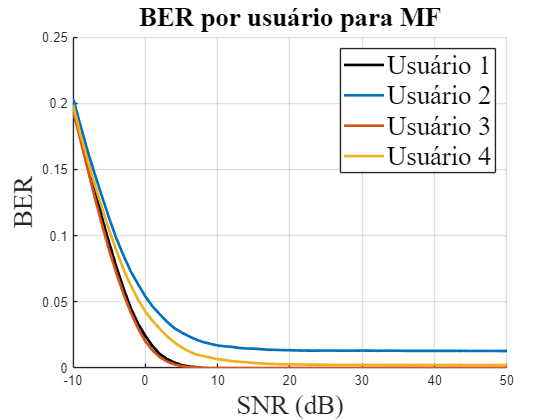


% Gráfico da BER para cada usuário usando MF
figure;
hold on;
for users_idx = 1:K
    % Plota a BER de cada usuário usando MF
    semilogy(SNR, BER_MF_individual(users_idx, :), 'LineWidth', linewidth, 'Color', colors(users_idx, :));
end
hold off;
xlabel('SNR (dB)', 'FontName', fontname, 'FontSize', fontsize);
ylabel('BER', 'FontName', fontname, 'FontSize', fontsize);
title('BER por usuário para MF', 'FontName', fontname, 'FontSize', fontsize);
legend(arrayfun(@(x) sprintf('Usuário %d', x), 1:K, 'UniformOutput', false), 'FontName', fontname, 'FontSize', fontsize);
grid on;